# サッカー　国際試合の結果から各国チームのEloレーティングを求める

clear;clc;close all;

データの読み込みと前処理

opts = detectImportOptions('../../data/archive/results.csv');
opts = setvaropts(opts, 'date', 'InputFormat', 'yyyy/MM/dd');

tbl=readtable('../../data/archive/results.csv',opts,'encoding','UTF-8');
teamNames=unique([tbl.home_team;tbl.away_team]);
tbl.home_team=categorical(tbl.home_team,teamNames);
tbl.away_team=categorical(tbl.away_team,teamNames);
teamNames=categorical(teamNames);
tbl.tournament=categorical(tbl.tournament);
tbl.neutral=str2mat(tbl.neutral)

tbl = 47598×9 table
       date       home_team    away_team    home_score    away_score    tournament       city          country       neutral
    __________    _________    _________    __________    __________    __________    ___________    ____________    _______

    1872/11/30    Scotland     England          0             0          Friendly     {'Glasgow'}    {'Scotland'}     FALSE 
    1873/03/08    England      Scotland         4             2          Friendly     {'London' }    {'England' }     FALSE 
    1874/03/07    Scotland     England          2             1          Friendly     {'Glasgow'}    {'Scotland'}     FALSE 
    1875/03/06    England      Scotland         2             2          Friendly     {'London' }    {'England' }     FALSE 
    1876/03/04    Scotland     England          3             0          Friendly     {'Glasgow'}    {'Scotland'}     FALSE 
    1876/03/25    Scotland     Wales            4             0          Friendly     {'Glasgow'}    {'S


summary(tbl)

Variables:

    date: 47598×1 datetime

        Values:

            Min       1872/11/30
            Median    1999/08/18
            Max       2024/09/10

    home_team: 47598×1 categorical

        Values:

            Abkhazia                               22   
            Afghanistan                            46   
            Albania                               201   
            Alderney                               48   
            Algeria                               335   
            Ambazonia                               0   
            American Samoa                         24   
            Andalusia                              12   
            Andorra                               107   
            Angola                                194   
            Anguilla                               28   
            Antigua and Barbuda                   125   
            Arameans Suryoye                        3   
            Arg

Eloレーティング算出(ホームアドバンテージを考慮しない)

r=zeros(size(teamNames));
K=log(10)/400*32

K = 0.1842

EloA=zeros(size(tbl,1),1);
EloB=zeros(size(tbl,1),1);

for n1=1:size(tbl,1)
    taName=tbl.home_team(n1);
    tbName=tbl.away_team(n1);
    taNum=find(teamNames==taName);
    tbNum=find(teamNames==tbName);

    EloA(n1)=r(taNum);
    EloB(n1)=r(tbNum);

    taGoals=tbl.home_score(n1);
    tbGoals=tbl.away_score(n1);

    % 結果
    if taGoals>tbGoals
        s=1;
    elseif taGoals==tbGoals
        s=0.5;
    else
        s=0;
    end

    % 予測勝率
    taRating=r(taNum);
    tbRating=r(tbNum);

    p=1./(1+exp(tbRating-taRating));
    r(taNum)=r(taNum)+K*(s-p);
    r(tbNum)=r(tbNum)-K*(s-p);

end

チームの情報を示すtableをつくる

tbl_team=table();
tbl_team=addvars(tbl_team, ...
    teamNames,'NewVariableNames','Team');
tbl_team=addvars(tbl_team, ...
    r,'NewVariableNames','EloRating');
tbl_team=addvars(tbl_team, ...
    countcats([tbl.home_team;tbl.away_team]), ...
    'NewVariableNames','Matches');

試合前のレーティング値をtblに追加

tbl=addvars(tbl, EloA,EloB);

tbl_team=sortrows(tbl_team,"EloRating","descend")

tbl_team = 336×3 table
       Team        EloRating    Matches
    ___________    _________    _______

    Argentina       3.3073       1049  
    Spain           3.1306        760  
    Colombia        2.9528        620  
    France          2.7318        910  
    Brazil          2.6161       1042  
    England          2.612       1072  
    Portugal        2.5483        677  
    Netherlands     2.5444        853  
    Germany         2.4644       1010  
    Italy           2.4427        866  
    Belgium         2.3632        829  
    Japan           2.2677        782  
    Croatia         2.2494        378  
    Uruguay         2.2237        950  
    Denmark         2.1541        852  
    Iran            2.0674        596  


図示

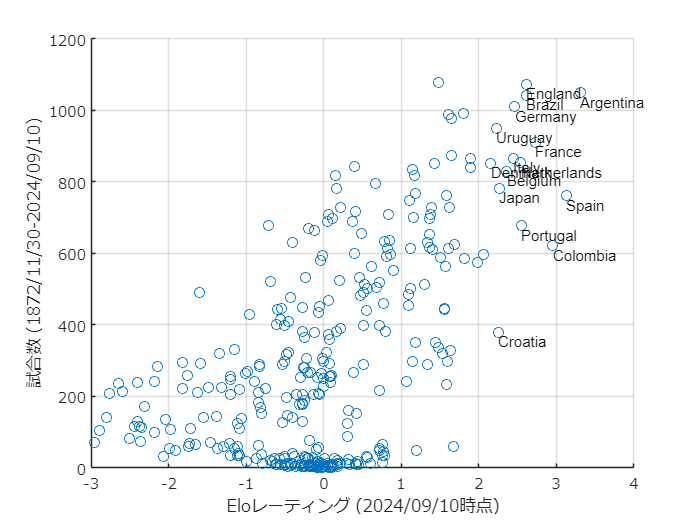

figure;
scatter(tbl_team.EloRating, tbl_team.Matches);hold on;grid on;
set(gca,'fontname','メイリオ');
xlabel(['Eloレーティング (' datestr(max(tbl.date),'yyyy/mm/dd') '時点)']);
ylabel(['試合数 (' datestr(min(tbl.date),'yyyy/mm/dd') '-' datestr(max(tbl.date),'yyyy/mm/dd') ')' ]);
for n1=1:15
    text(tbl_team.EloRating(n1), tbl_team.Matches(n1),[' ' tbl_team.Team(n1)], ...
        'fontname','Arial')
end
exportgraphics(gcf,'fig_internationalFootball_EloRaing.pdf');

履歴の図示

myTeamNames={'Argentina','Germany','Japan'};
figure;hold on;
for myTeamName=myTeamNames
    myTeamName
    ind_home=tbl.home_team==myTeamName;
    ind_away=tbl.away_team==myTeamName;
    ind=ind_home | ind_away;

    tbl_tmp=tbl(ind,:)
    myTeamRating ...
        =tbl_tmp.EloA.*(tbl_tmp.home_team==myTeamName) ...
        + tbl_tmp.EloB.*(tbl_tmp.away_team==myTeamName);
    plot(tbl_tmp.date, myTeamRating)
end

myTeamName = 1×1 の cell 配列
    {'Argentina'}


tbl_tmp = 1049×11 table
       date       home_team    away_team    home_score    away_score            tournament                   city             country       neutral       EloA         EloB   
    __________    _________    _________    __________    __________    ___________________________    ________________    _____________    _______    __________    _________

    1902/07/20    Uruguay      Argentina        0             6         Friendly                       {'Montevideo'  }    {'Uruguay'  }     FALSE              0            0
    1903/09/13    Argentina    Uruguay          2             3         Friendly                       {'Buenos Aires'}    {'Argentina'}     FALSE       0.092103    -0.092103
    1905/08/15    Argentina    Uruguay          0             0         Copa Lipton                    {'Buenos Aires'}    {'Argentina'}     FALSE     -0.0084591    0.0084591
    1906/08/15    Uruguay      Argentina        0             2         Copa Lipton                 

myTeamName = 1×1 の cell 配列
    {'Germany'}


tbl_tmp = 1010×11 table
       date        home_team      away_team     home_score    away_score    tournament        city             country        neutral      EloA          EloB   
    __________    ___________    ___________    __________    __________    __________    _____________    _______________    _______    _________    __________

    1908/04/05    Switzerland    Germany            5             3          Friendly     {'Basel'    }    {'Switzerland'}     FALSE      -0.18007             0
    1908/06/07    Austria        Germany            3             2          Friendly     {'Vienna'   }    {'Austria'    }     FALSE       0.04204      -0.10037
    1909/04/04    Germany        Switzerland        1             0          Friendly     {'Karlsruhe'}    {'Germany'    }     FALSE      -0.18593     -0.079696
    1909/04/04    Hungary        Germany            3             3          Friendly     {'Budapest' }    {'Hungary'    }     FALSE       0.10467     -0.088939
    1910/

myTeamName = 1×1 の cell 配列
    {'Japan'}


tbl_tmp = 782×11 table
       date        home_team      away_team     home_score    away_score              tournament                   city            country        neutral       EloA          EloB   
    __________    ___________    ___________    __________    __________    _______________________________    ____________    _______________    _______    __________    __________

    1917/05/07    Japan          Philippines        2             15        Friendly                           {'Tokyo'   }    {'Japan'      }     FALSE              0     -0.016145
    1917/05/09    Japan          China PR           0              5        Far Eastern Championship Games     {'Tokyo'   }    {'Japan'      }     FALSE      -0.092847      0.016145
    1917/05/10    Japan          Philippines        2             15        Far Eastern Championship Games     {'Tokyo'   }    {'Japan'      }     FALSE       -0.17994      0.076702
    1921/05/30    Japan          Philippines        0             

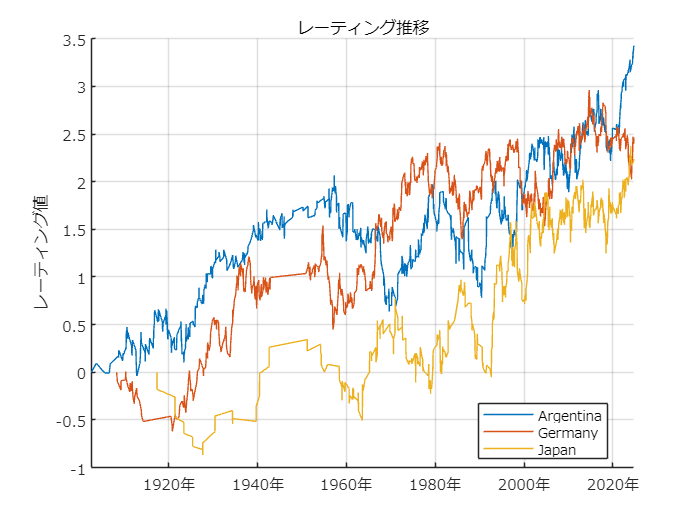

grid on;set(gca,'fontname','メイリオ');
legend(myTeamNames,'Location','best');
title('レーティング推移');
ylabel('レーティング値');
exportgraphics(gcf,'fig_internationalFootball_EloRatingHistory.pdf');